## Combined Exp

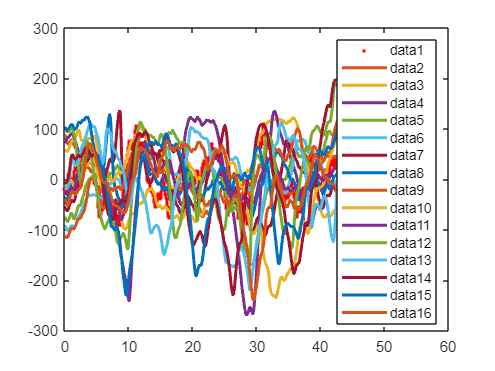

experiments = {
    % 'samsun low light window 7cm\7cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_04_22_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_08_20_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_10_11_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_11_50_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_13_41_2022_TRACK.xlsx',
    
    'Data\samsun low light window 21cm\21cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_46_43_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_48_50_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_50_57_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_54_12_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_56_25_2022_TRACK.xlsx',
    
    'Data\samsun low light window 14cm\14cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_54_05_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_56_51_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_00_01_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_02_22_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_04_12_2022_TRACK.xlsx',
   
    'Data\samsun low light nowindow 21cm\21cm\trial01_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_03_18_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_07_26_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial04_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_09_31_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial05_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_11_33_2022_TRACK.xlsx',
    };

% readtable("samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx")

fishes = [];

for experimentIdx = 1:length(experiments)
    experiment = experiments{experimentIdx};
    table = readtable(experiment);
    fish = table.Fish;
    fish = fish(76:end);
    fishes = [fishes detrend(fish)];
end

table_0 = readtable(experiments{1});
cage = table_0.Cage;
cage = cage(76:end);
cage = detrend(cage);

Fs = 25;              % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(cage);     % Length of signal
t = (0:L-1)*T;        % Time vector
f = Fs/L*(0:L-1);

figure,
hold on; box on;
plot(t, cage, '.r', 'LineWidth', 4);

for fish = fishes
    Fs = 25;
    t = 0:1/Fs:(length(fish)-1)/Fs;

    plot(t, fish, 'LineWidth', 2);
end

legend()

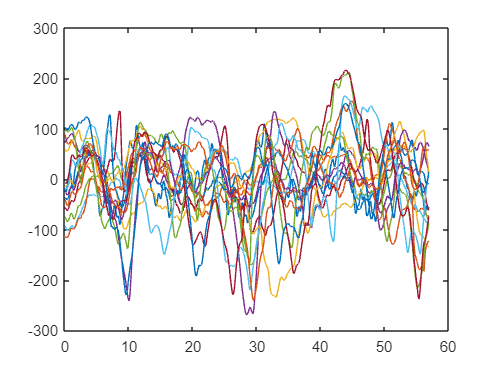

y = fishes;
u = cage;
num_outputs = length(y(1,:));

% Create an iddata object with your data
data = iddata(y, u, t(2) - t(1), 'ExperimentName', experiments);

figure, hold on, box on,
plot(t, u, t, y);

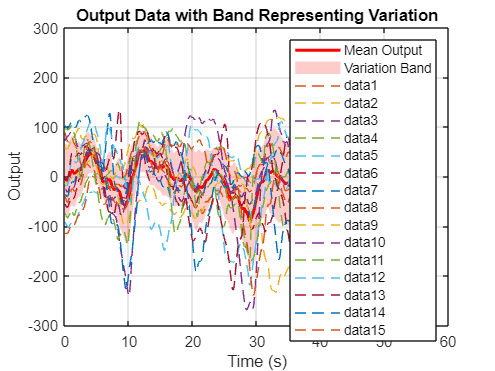

% Calculate the mean and standard deviation at each time point
y_mean = mean(y, 2);
y_std = std(y, 0, 2);

% Define the upper and lower bounds for the band
y_upper = y_mean + y_std;
y_lower = y_mean - y_std;

% Plot the mean output
figure;
plot(t, y_mean, 'r', 'LineWidth', 2);
hold on;

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
legend('Mean Output', 'Variation Band');
grid on;

% Optional: Plot individual output data
for i = 1:num_outputs
    plot(t, y(:, i), '--');
end

% Number of models to fit
num_models = 3;

% Initialize cell array for storing models
G_ests = cell(num_models, num_outputs);

% Define the transfer function structure for the model
K_initial = 1; % Initial guess for K
a_initial = 1; % Initial guess for a
tau_initial = 0.5; % Initial guess for tau
A_initial = 1;
w0_initial = 1;
etha_initial = 0.5;

% Loop through each output to estimate the model
for i = 1:num_outputs
    % Create idtf model with initial parameter values
    G0 = idtf(K_initial, [1 a_initial]);
    G1 = idtf(K_initial, [1 a_initial], 'InputDelay', tau_initial);
    G2 = idtf(A_initial*w0_initial^2, [1 2*etha_initial*w0_initial w0_initial^2], 'InputDelay', tau_initial);

    % Estimate the model parameters for each output
    G_ests{1, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G0);
    G_ests{2, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G1);
    G_ests{3, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G2);
end

% Display the estimated 
% models
for i = 1:num_outputs
    for j = 1:num_models
        G_ests{j, i}
    end
end

ans =
  From input "u1" to output "y1":
   0.8199
  --------
  s + 1.57
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                 
Estimated using PEM on time domain data.
Fit to estimation data: 19.39%          
FPE: 1098, MSE: 1093                    
 
Model Properties

ans =
  From input "u1" to output "y1":
                  1.758
  exp(-0.5*s) * ---------
                s + 4.065
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients

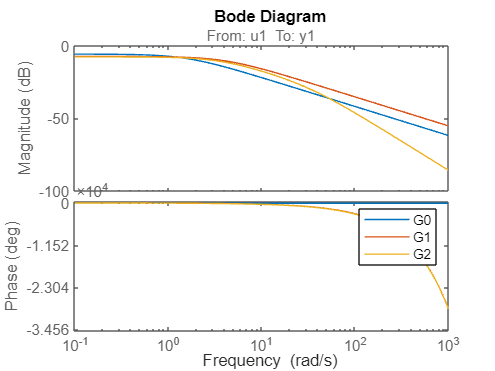

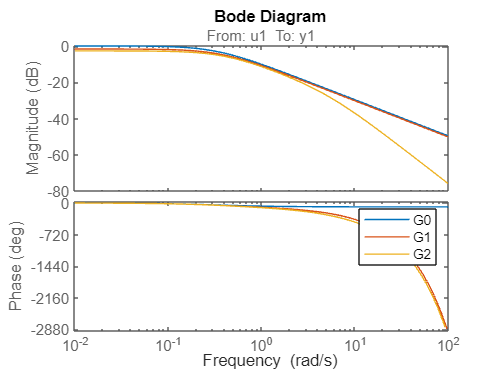

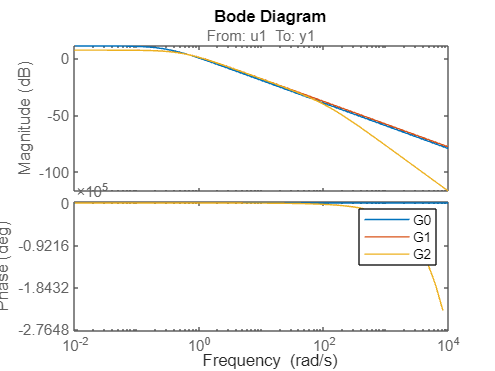

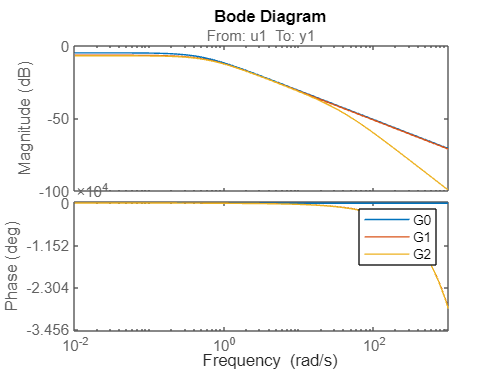

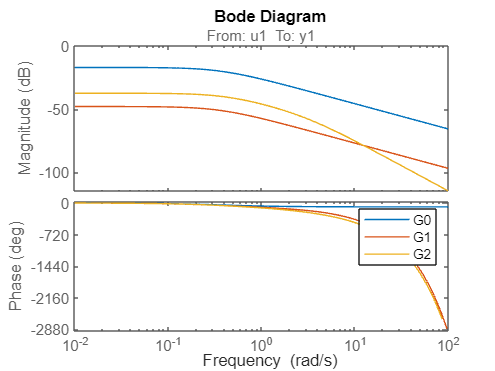

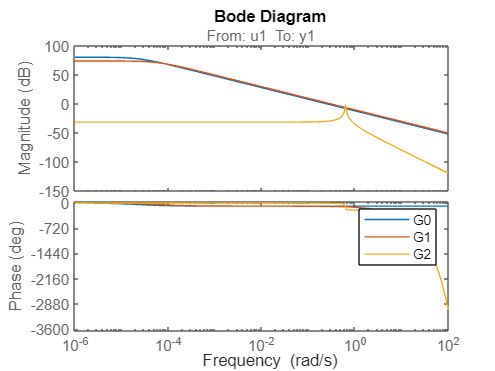

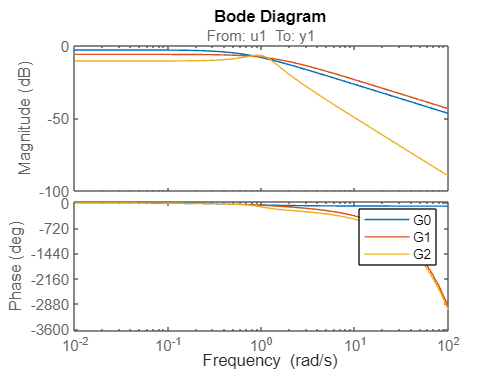

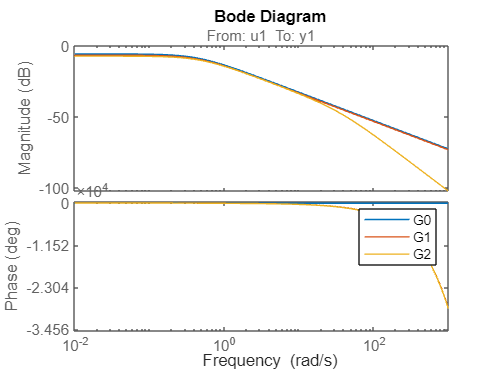

for i = 1:num_outputs
    figure, hold on, box on,
    for j = 1:num_models
        h = bodeplot(G_ests{j, i});
        % showConfidence(h,3)
    end
    legend('G0', 'G1', 'G2');
end

% Initialize cell array for storing sim outputs
% y_sims = zeros(size(y));
y_sims = cell(num_models, num_outputs);

% Simulate the model output
for i = 1:num_outputs
    for j = 1:num_models
        y_sims{j, i} = lsim(G_ests{j, i}, u, t);
    end
end

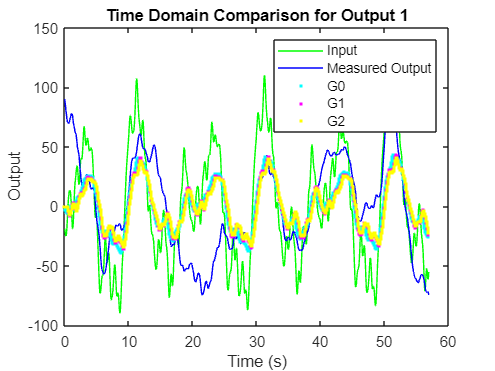

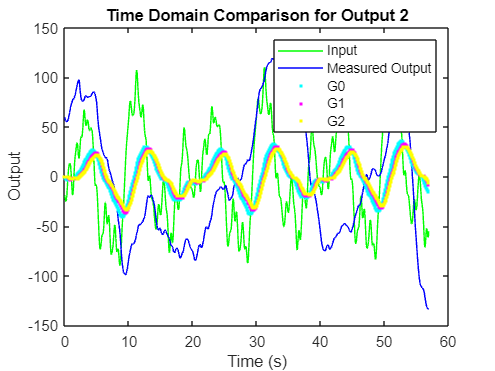

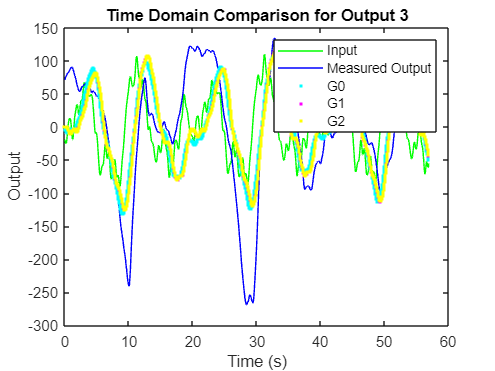

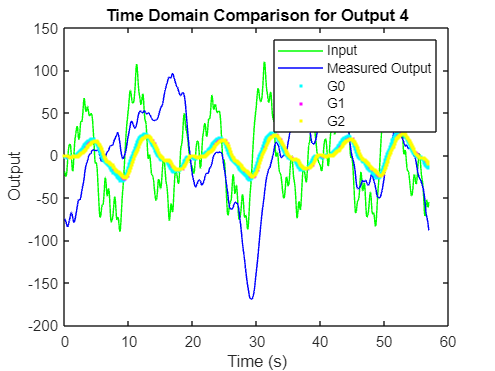

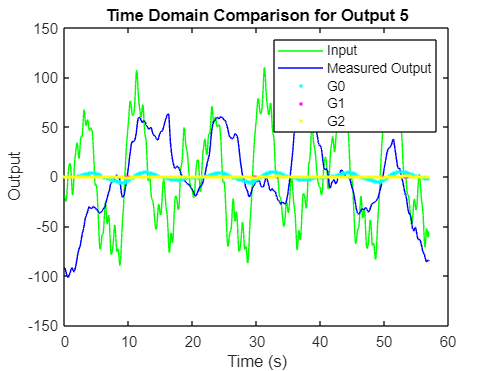

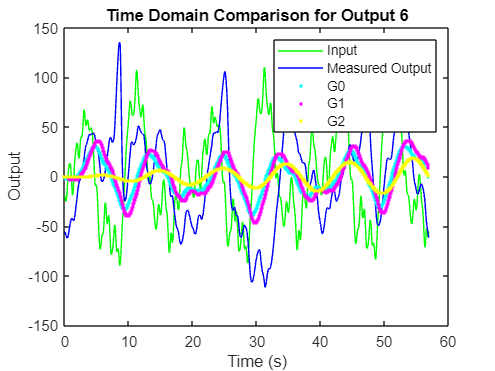

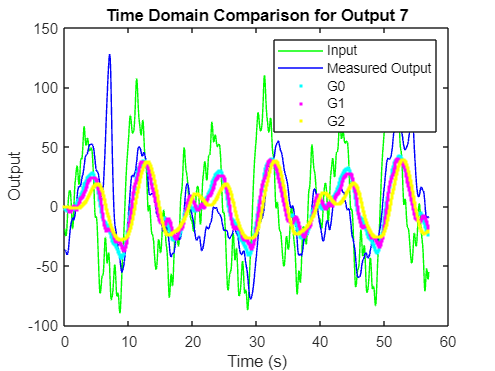

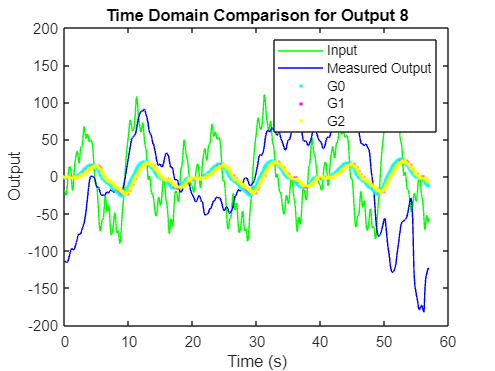

% Plot the measured output vs. simulated output in the time domain
for i = 1:num_outputs
    figure; hold on, box on,

    % subplot(num_outputs, 1, i);
    plot(t, u, 'g', t, y(:, i), 'b');
    plot(t, y_sims{1, i}, 'c.');
    plot(t, y_sims{2, i}, 'm.');
    plot(t, y_sims{3, i}, 'y.');

    legend('Input', 'Measured Output', 'G0', 'G1', 'G2');
    xlabel('Time (s)');
    ylabel('Output');
    title(['Time Domain Comparison for Output ' num2str(i)]);
end

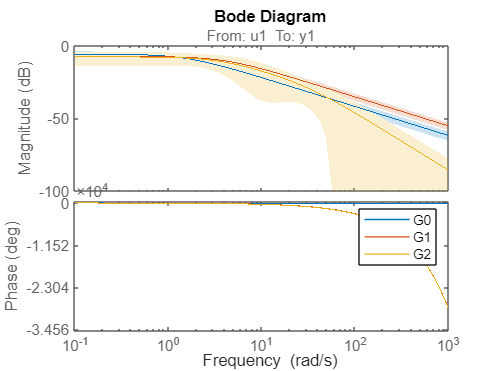

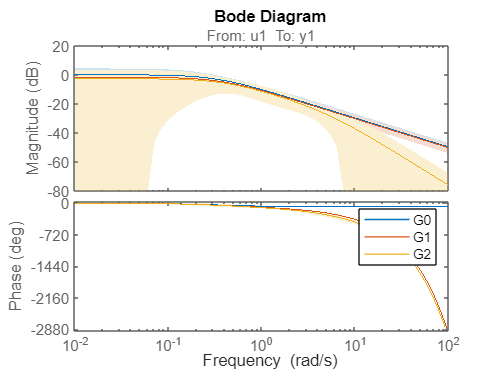

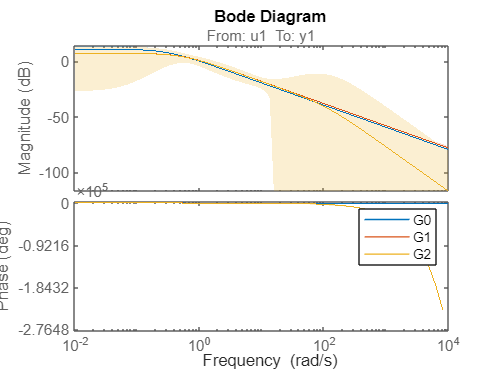

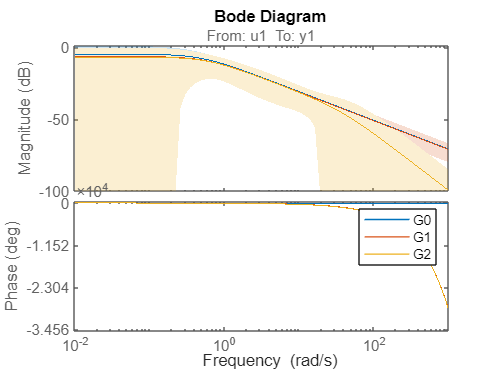

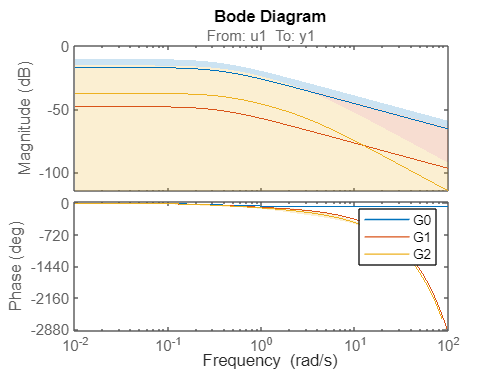

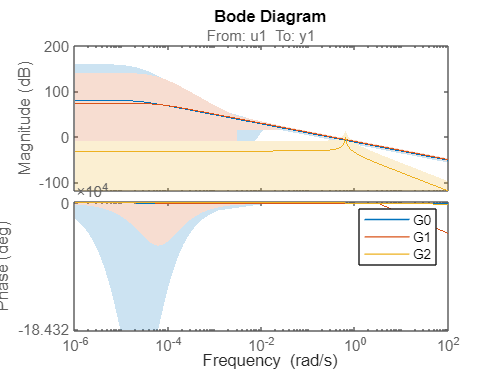

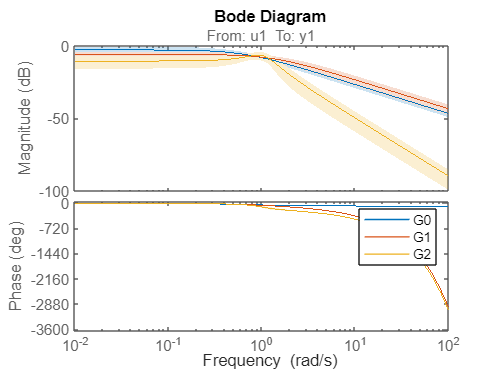

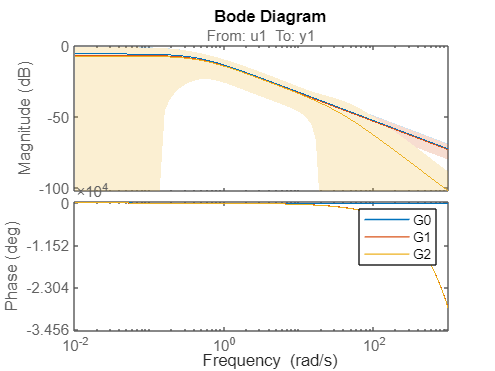

for i = 1:num_outputs
    figure, hold on,
    for j = 1:num_models
        h = bodeplot(G_ests{j, i});
        showConfidence(h,1)
    end
    legend('G0', 'G1', 'G2')
end

### Standard Deviation

% Convert cell array to matrix for statistical analysis
y_est = zeros(length(t), num_models, num_outputs);

for i = 1:num_models
    for j = 1:num_outputs
        y_est(:, i, j) = y_sims{i, j};
    end
end

size(y_est)

ans =         1425           3          15


% Calculate the mean and standard deviation at each time point
y_mean = mean(y, 2);
y_std = std(y, 0, 2);

% Define the upper and lower bounds for the band
y_upper = y_mean + y_std;
y_lower = y_mean - y_std;

% Preallocate arrays for storing means and standard deviations
y_est_mean = zeros(length(t), num_models);
y_est_std = zeros(length(t), num_models);
y_est_upper = zeros(length(t), num_models);
y_est_lower = zeros(length(t), num_models);

% Compute the mean and standard deviation at each time point for each model's outputs
for i = 1:num_models
    y_est_mean(:, i) = mean(y_est(:, i, :), 3);
    y_est_std(:, i) = std(y_est(:, i, :), 0, 3);
    y_est_upper(:, i) = y_est_mean(:, i) + y_est_std(:, i);
    y_est_lower(:, i) = y_est_mean(:, i) - y_est_std(:, i);
end

#### Output Data with Band Representing Variation

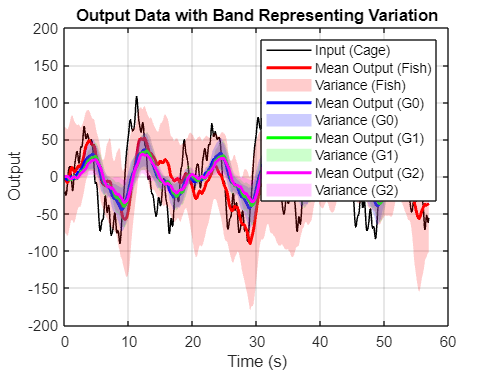

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
for i = 1:num_models
    plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
    fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');
end

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G0)', 'Variance (G0)', 'Mean Output (G1)', 'Variance (G1)', 'Mean Output (G2)', 'Variance (G2)');

G0 Only

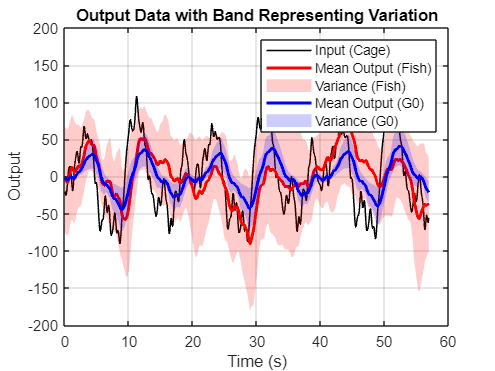

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
i = 1;
plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G0)', 'Variance (G0)');

G1 only

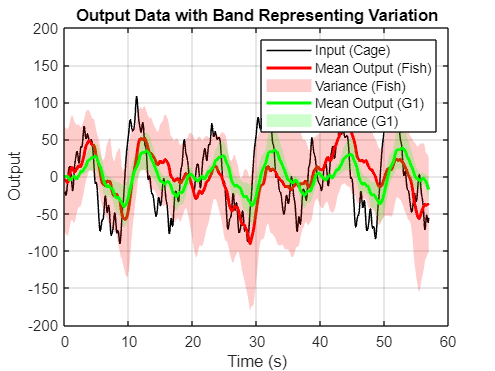

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
i = 2;
plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G1)', 'Variance (G1)');

G2 only

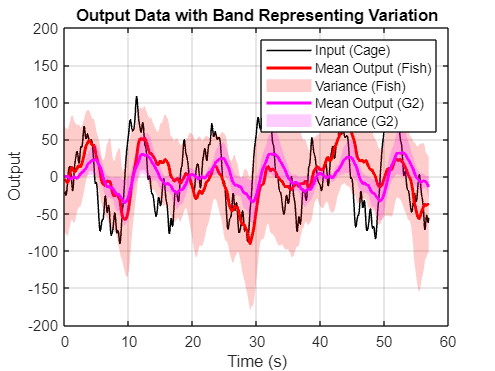

figure; 

% Plot the input
plot(t, u, 'k', 'LineWidth', 1);
hold on;

% Plot the mean output
plot(t, y_mean, 'r', 'LineWidth', 2);

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
i = 3;
plot(t, y_est_mean(:, i), colors(i), 'LineWidth', 2);
fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

legend('Input (Cage)', 'Mean Output (Fish)', 'Variance (Fish)', 'Mean Output (G2)', 'Variance (G2)');

### Error ANOVA

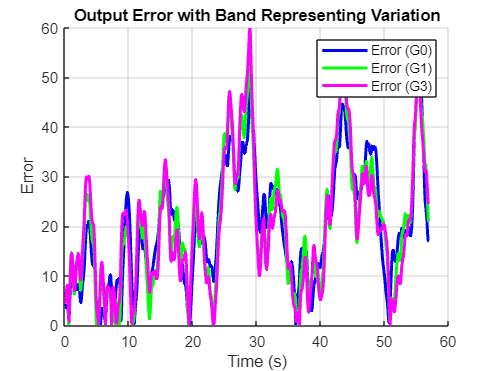

figure; hold on;

% Add labels and title
xlabel('Time (s)');
ylabel('Error');
title('Output Error with Band Representing Variation');
grid on;

% Plot the mean estimated outputs and their bands
colors = ['b', 'g', 'm']; % Different colors for different models
for i = 1:num_models
    plot(t, abs(y_mean - y_est_mean(:, i)), colors(i), 'LineWidth', 2);
    % fill([t'; flipud(t')], [y_est_upper(:, i); flipud(y_est_lower(:, i))], colors(i), 'FaceAlpha', 0.2, 'EdgeColor', 'none');
end

legend('Error (G0)', 'Error (G1)', 'Error (G3)');

#### Cumulative errors:

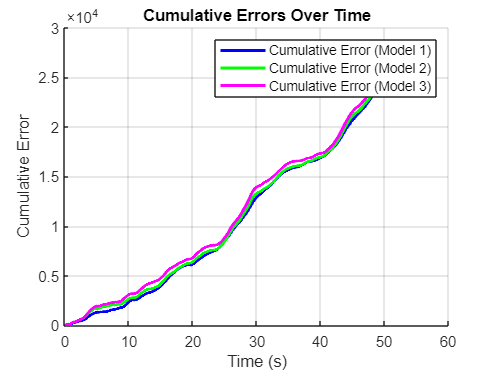

figure; hold on;

% Add labels and title
xlabel('Time (s)');
ylabel('Cumulative Error');
title('Cumulative Errors Over Time');
grid on;

% Plot the cumulative errors for the mean estimated outputs
colors = ['b', 'g', 'm']; % Different colors for different models
for i = 1:num_models
    % Calculate the absolute error
    abs_error = abs(y_mean - y_est_mean(:, i));
    
    % Calculate the cumulative sum of the absolute error
    cumulative_error = cumsum(abs_error);
    
    % Plot the cumulative error
    plot(t, cumulative_error, colors(i), 'LineWidth', 2);
end

% Add legend
legend('Cumulative Error (Model 1)', 'Cumulative Error (Model 2)', 'Cumulative Error (Model 3)');

#### Histogram of errors:

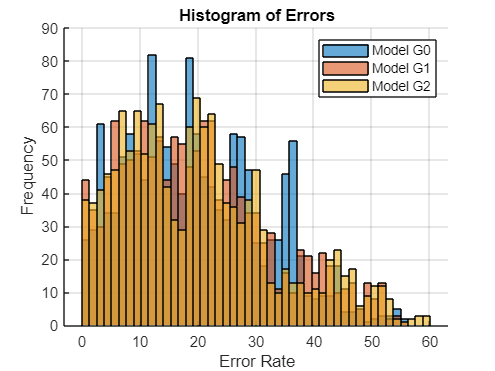

% Plot histograms of errors
figure; hold on;

% Add labels and title
xlabel('Error Rate');
ylabel('Frequency');
title('Histogram of Errors');
grid on;

% Fixed bin width
bin_width = 1 / Fs * 32; % Specify your desired bin width

% Plot histograms for each model
for i = 1:num_models
    % Calculate the absolute error
    abs_error = abs(y_mean - y_est_mean(:, i));
    histogram(abs_error, 'BinWidth', bin_width, 'DisplayName', ['Model G', num2str(i-1)]);
end

% Add legend
legend show;

## Frequency domain analyses

% Frequency domain analysis
% Compute the FFT of the measured and estimated outputs
Y_mean = fft(y_mean);
Y_est_mean = fft(y_est_mean);

% Define frequency vector
Fs = 1 / (t(2) - t(1)); % Sampling frequency
N = length(t);
f = (0:N-1)*(Fs/N); % Frequency vector

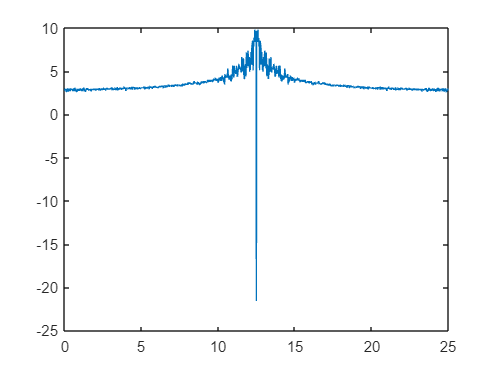

figure,
plot(f, log(fftshift(Y_mean)));

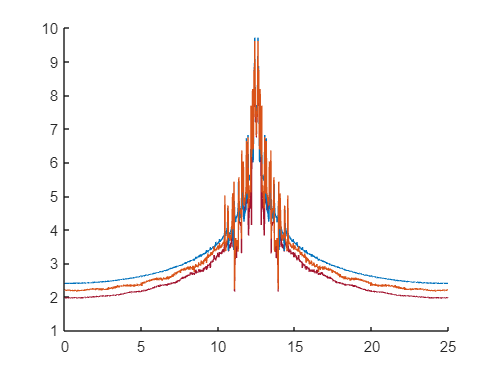

figure, hold on,
for i = 1:num_models
    plot(f, log(fftshift(Y_est_mean)));
end

% Calculate absolute errors in the frequency domain
abs_errors_freq = abs(Y_mean - Y_est_mean);

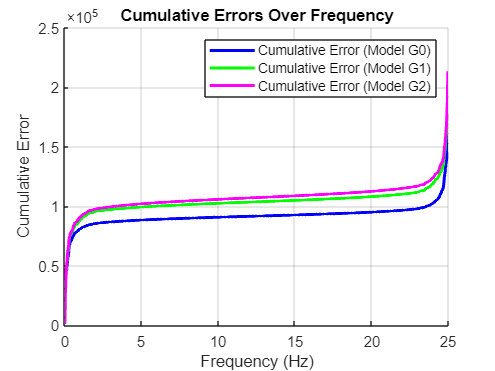

% Plot cumulative errors over frequency
figure; hold on;

% Add labels and title
xlabel('Frequency (Hz)');
ylabel('Cumulative Error');
title('Cumulative Errors Over Frequency');
grid on;

% Plot the cumulative errors for the mean estimated outputs in the frequency domain
for i = 1:num_models
    % Calculate the cumulative sum of the absolute error
    cumulative_error_freq = cumsum(abs_errors_freq(:, i));
    
    % Plot the cumulative error
    plot(f, cumulative_error_freq, colors(i), 'LineWidth', 2);
end

% Add legend
legend('Cumulative Error (Model G0)', 'Cumulative Error (Model G1)', 'Cumulative Error (Model G2)');

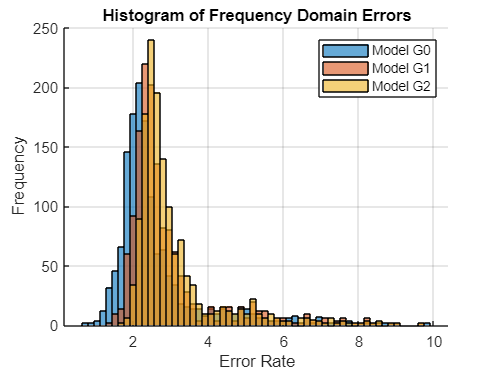

% Plot histograms of frequency domain errors
figure; hold on;

% Add labels and title
xlabel('Error Rate');
ylabel('Frequency');
title('Histogram of Frequency Domain Errors');
grid on;

% Fixed bin width
bin_width = 1 / Fs * 4; % Specify your desired bin width

% Plot histograms for each model in the frequency domain
for i = 1:num_models
    histogram(log(abs_errors_freq(:, i)), 'BinWidth', bin_width, 'DisplayName', ['Model G', num2str(i-1)]);
end

% Add legend
legend show;

### Phase Response Error Comparison

% Calculate phase responses
phase_Y_mean = angle(Y_mean);
phase_Y_est_mean = angle(Y_est_mean);

% Calculate phase errors
phase_errors = log(unwrap(phase_Y_mean) - unwrap(phase_Y_est_mean));

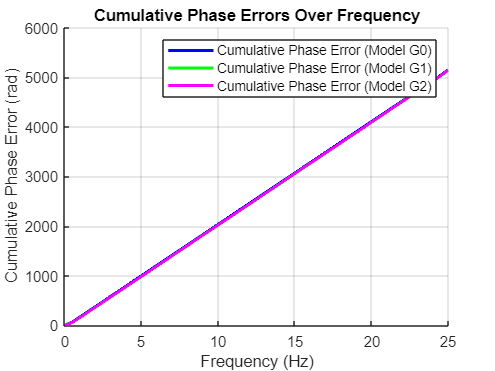

% Plot cumulative phase errors over frequency
figure; hold on;

% Add labels and title
xlabel('Frequency (Hz)');
ylabel('Cumulative Phase Error (rad)');
title('Cumulative Phase Errors Over Frequency');
grid on;

% Plot the cumulative phase errors for the mean estimated outputs in the frequency domain
for i = 1:num_models
    % Calculate the cumulative sum of the phase error
    cumulative_phase_error = cumsum(abs(phase_errors(:, i)));
    
    % Plot the cumulative phase error
    plot(f, cumulative_phase_error, colors(i), 'LineWidth', 2);
end

% Add legend
legend('Cumulative Phase Error (Model G0)', 'Cumulative Phase Error (Model G1)', 'Cumulative Phase Error (Model G2)');

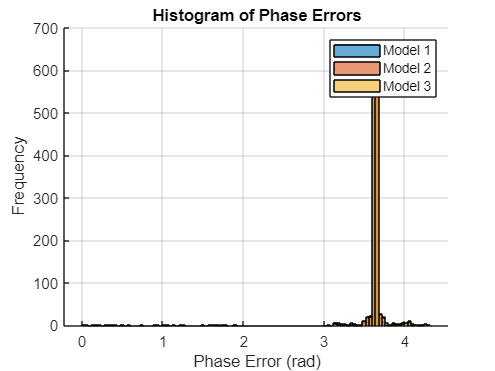

% Plot histograms of phase errors
figure; hold on;

% Add labels and title
xlabel('Phase Error (rad)');
ylabel('Frequency');
title('Histogram of Phase Errors');
grid on;

% Fixed bin width
bin_width = 1 / Fs * 1; % Specify your desired bin width

% Plot histograms for each model in the frequency domain
for i = 1:num_models
    histogram(abs(phase_errors(:, i)), 'BinWidth', bin_width, 'DisplayName', ['Model ', num2str(i)]);
end

% Add legend
legend show;

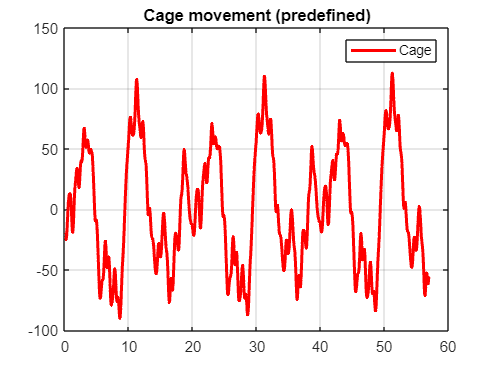

figure,
hold on; box on; grid on;
title('Cage movement (predefined)')
plot(t, cage, 'r', 'LineWidth', 2);
legend('Cage');

## Fish Bode 

experiments = {
    % 'samsun low light window 7cm\7cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_04_22_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_08_20_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_10_11_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_11_50_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_13_41_2022_TRACK.xlsx',
    
    'Data\samsun low light window 21cm\21cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_46_43_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_48_50_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_50_57_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_54_12_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_56_25_2022_TRACK.xlsx',
    
    'Data\samsun low light window 14cm\14cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_54_05_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_56_51_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_00_01_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_02_22_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_04_12_2022_TRACK.xlsx',
   
    'Data\samsun low light nowindow 21cm\21cm\trial01_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_03_18_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_07_26_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial04_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_09_31_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial05_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_11_33_2022_TRACK.xlsx',
    };

% readtable("samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx")

fishes = [];

for experimentIdx = 1:length(experiments)
    experiment = experiments{experimentIdx};
    table = readtable(experiment);
    fish = table.Fish;
    fishes = [fishes detrend(fish)];
end

table_0 = readtable(experiments{1});
cage = table_0.Cage;
cage = detrend(cage);

Fs = 25;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(cage);             % Length of signal
t = (0:L-1)*T;        % Time vector
f = (-L/2:1:L/2-1)/Fs;

fishes

fishes =   252.0672   36.1758   94.2818 -146.5316  -93.0075  -75.1962   35.3962 -123.1638 -116.6884  -47.1552   -5.0870 -288.0090  -54.4156   62.8137 -226.1035
  252.9418   36.0168   95.2921 -145.6125  -93.0483  -75.2150   35.3988 -123.1059 -116.6931  -46.1392   -6.1485 -291.9579  -54.3109   63.8327 -229.0767
  253.8165   35.8579   96.3024 -144.6935  -93.0890  -75.2337   35.4014 -123.0481 -117.6978  -45.1231   -6.2101 -294.9069  -54.2061   63.8518 -233.0498
  254.6911   36.6990   97.3128 -142.7745  -93.1298  -74.2525   34.4040 -122.9903 -117.7025  -44.1071   -7.2716 -294.8558  -53.1014   65.8708 -234.0230
  254.5657   37.5401   97.3231 -137.8554  -93.1705  -74.2712   32.4066 -122.9324 -101.7073  -43.0910   -4.3332 -290.8048  -51.9967   66.8899 -228.9962
  251.4404   38.3812   97.3335 -127.9364  -92.2113  -71.2900   27.4092 -122.8746  -81.7120  -42.0750    1.6052 -285.7537  -50.8919   67.9089 -221.9693
  244.3150   38.2223   96.3438 -118.0174  -90.2520  -68.3087   18.4118 -122.8168  -66

cage

cage =    -4.2361
   -4.2310
   -7.2259
  -13.2208
  -19.2156
  -25.2105
  -27.2054
  -25.2003
  -23.1952
  -23.1901


fishes(:, 1)

ans =   252.0672
  252.9418
  253.8165
  254.6911
  254.5657
  251.4404
  244.3150
  234.1896
  224.0643
  212.9389


% figure,
% stem(f, abs(fftshift(fft(cage)))/L);
% hold on;

f_primes = [2 3 5 7 11 13 17 19 23 29 31 37 41] .* 3

f_primes =      6     9    15    21    33    39    51    57    69    87    93   111   123


prime_indices = [L/2+1 - f_primes L/2+1 + f_primes]

prime_indices =    745   742   736   730   718   712   700   694   682   664   658   640   628   757   760   766   772   784   790   802   808   820   838   844   862   874


C = abs(fftshift(fft(cage)))/L;
C_trimmed = zeros(L, 1);
C_trimmed(prime_indices) = C(prime_indices);

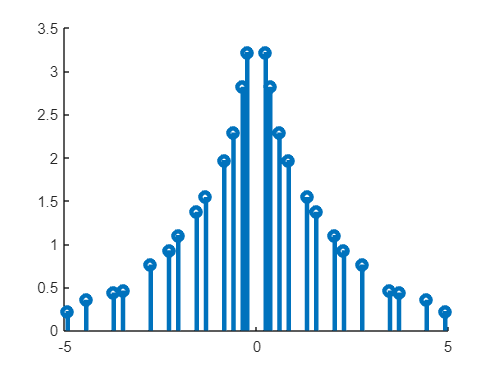

figure,
hold on;
stem(f, log(C_trimmed), 'LineWidth', 3);

G_acts = cell(1, num_outputs);

for i = 1:num_outputs
    fish = fishes(:, i);
    F = abs(fftshift(fft(fish)))/L;
    F_trimmed = zeros(L, 1);
    F_trimmed(prime_indices) = F(prime_indices);
    G_acts{1, i} = F_trimmed ./ C_trimmed;
end

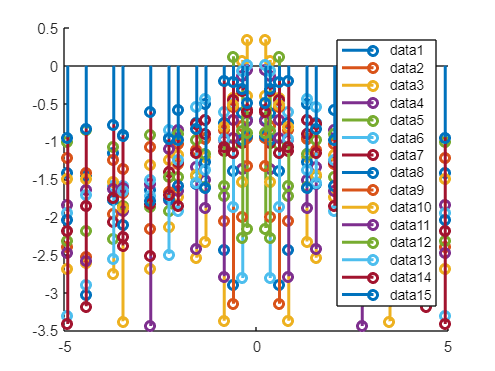

figure, hold on,

for i = 1:num_outputs
    stem(f, log(G_acts{1, i}), 'LineWidth', 2);
end

legend();

% for i = 1:num_outputs
%     figure,
%     bodeplot(G_acts{1, i}, f_primes ./ Fs .* 2*pi);
% end

% G_acts{1, 10}
% 
% bodeplot(G_acts{1, 1}, f_primes ./ Fs .* 2*pi);

f_primes = [2 3 5 7 11 13 17 19 23 29 31 37 41] .* 3;
prime_indices = [L/2+1 - f_primes L/2+1 + f_primes];
w_primes = f_primes ./ Fs .* 2*pi

w_primes =     1.5080    2.2619    3.7699    5.2779    8.2938    9.8018   12.8177   14.3257   17.3416   21.8655   23.3734   27.8973   30.9133



C = fft(cage);
C_trimmed = zeros(L, 1);
C_trimmed(prime_indices) = C(prime_indices);

H_act = [];

figure,
hold on, box on,

for fish = fishes
    F = fft(fish);
    F_trimmed = zeros(L, 1);
    F_trimmed(prime_indices) = F(prime_indices);

    H = F_trimmed ./ C_trimmed;

    H_tf = frd(H, f*2*pi);
    H_act = [H_act H_tf];

    bodeplot(H_tf, w_primes);
end

for i = 1:num_outputs
    for j = 1:num_models
        bodeplot(G_ests{j, i}, w_primes);
    end
end

legend()

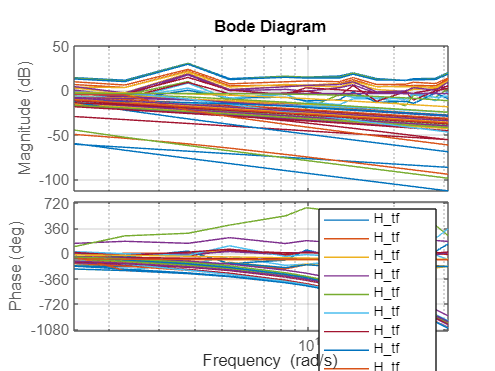

grid on

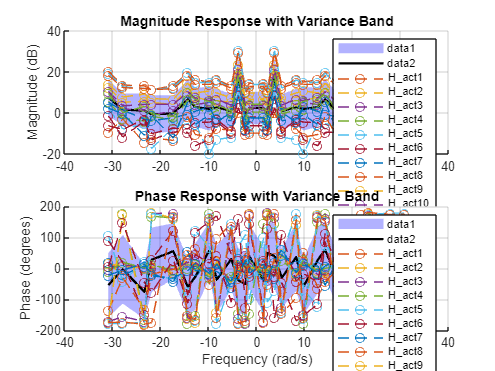

% Initialize arrays to store filtered responses
filtered_freq = cell(1, length(H_act));
filtered_mag = cell(1, length(H_act));
filtered_phase = cell(1, length(H_act));

% Filter out NaN values from frequency, magnitude, and phase data
for k = 1:length(H_act)
    freq = H_act(k).Frequency;
    mag = 20*log10(abs(squeeze(H_act(k).ResponseData)));
    ph = rad2deg(angle(squeeze(H_act(k).ResponseData)));
    
    valid_idx = ~isnan(freq) & ~isnan(mag) & ~isnan(ph);
    
    filtered_freq{k} = freq(valid_idx);
    filtered_mag{k} = mag(valid_idx);
    filtered_phase{k} = ph(valid_idx);
end

% Create arrays to store the filtered data for mean and variance calculations
all_freqs = unique(cell2mat(filtered_freq'));
mag_responses = nan(length(all_freqs), length(H_act));
phase_responses = nan(length(all_freqs), length(H_act));

for k = 1:length(H_act)
    [~, idx] = ismember(filtered_freq{k}, all_freqs);
    mag_responses(idx, k) = filtered_mag{k};
    phase_responses(idx, k) = filtered_phase{k};
end

% Calculate the mean and variance of the magnitude and phase responses
mean_mag = nanmean(mag_responses, 2);
mean_phase = nanmean(phase_responses, 2);
var_mag = nanvar(mag_responses, 0, 2);
var_phase = nanvar(phase_responses, 0, 2);

% Create a figure for the plots
figure;

% Plot Magnitude with variance band
subplot(2, 1, 1);
hold on;
% Plot variance band
fill([all_freqs; flip(all_freqs)], [mean_mag + sqrt(var_mag); flip(mean_mag - sqrt(var_mag))], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% Plot mean line
semilogx(all_freqs, mean_mag, 'k', 'LineWidth', 1.5);
% Plot individual responses (optional)
for k = 1:length(H_act)
    semilogx(filtered_freq{k}, filtered_mag{k}, 'DisplayName', ['H\_act' num2str(k)], 'LineStyle', '--', 'Marker', 'o');
end
hold off;
grid on;
title('Magnitude Response with Variance Band');
ylabel('Magnitude (dB)');
legend show;

% Plot Phase with variance band
subplot(2, 1, 2);
hold on;
% Plot variance band
fill([all_freqs; flip(all_freqs)], [mean_phase + sqrt(var_phase); flip(mean_phase - sqrt(var_phase))], 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% Plot mean line
semilogx(all_freqs, mean_phase, 'k', 'LineWidth', 1.5);
% Plot individual responses (optional)
for k = 1:length(H_act)
    semilogx(filtered_freq{k}, filtered_phase{k}, 'DisplayName', ['H\_act' num2str(k)], 'LineStyle', '--', 'Marker', 'o');
end
hold off;
grid on;
title('Phase Response with Variance Band');
ylabel('Phase (degrees)');
xlabel('Frequency (rad/s)');
legend show;